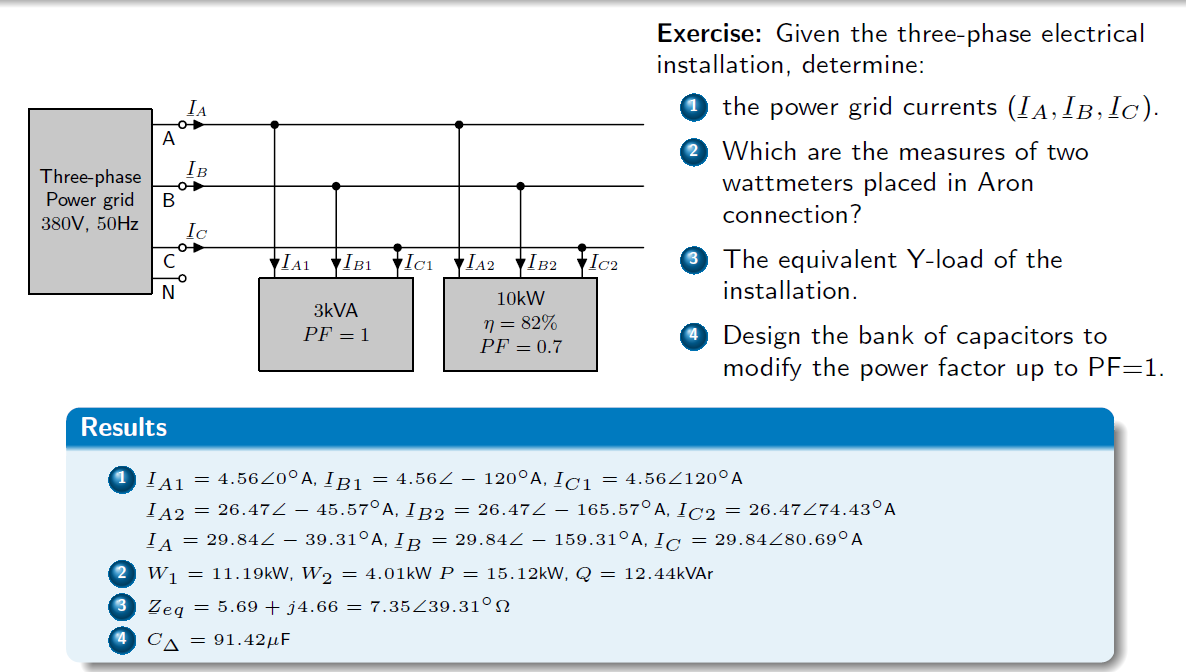

% Load 1
% Symm and eq
clear all

S1=3e3

S1 = 3000

cosfi=1

cosfi = 1

P1=S1*cosfi

P1 = 3000

U=380

U = 380

a=1*exp(1i*120*pi/180)

a = -0.5000 + 0.8660i


I=P1/(sqrt(3)*U*cosfi)

I = 4.5580

Ia1=I;
X=Ia1;disp(['Ia1=' num2str(abs(X)) ',' num2str(angle(X)*180/pi) 'A'])

Ia1=4.558,0A


Ib1=I*a^2;
X=Ib1;disp(['Ib1=' num2str(abs(X)) ',' num2str(angle(X)*180/pi) 'A'])

Ib1=4.558,-120A


Ic1=I*a;
X=Ic1;disp(['Ic1=' num2str(abs(X)) ',' num2str(angle(X)*180/pi) 'A'])

Ic1=4.558,120A




%Load 2
%fi-load angle

Pm2=10e3

Pm2 = 10000

n=0.82

n = 0.8200

P2=Pm2/n

P2 = 1.2195e+04

cosfi=0.7

cosfi = 0.7000

fi=acos(cosfi)*180/pi

fi = 45.5730

I2=P2/(sqrt(3)*U*cosfi)

I2 = 26.4694

Q2=P2*tan(fi*pi/180)

Q2 = 1.2442e+04


I2

I2 = 26.4694

fi

fi = 45.5730

Ia2=I2*exp(1i*-fi*pi/180)

Ia2 = 18.5286 - 18.9029i

X=Ia2;disp(['Ia2=' num2str(abs(X)) ',' num2str(angle(X)*180/pi) 'A'])

Ia2=26.4694,-45.573A


Ib2=Ia2*a^2;
X=Ib2;disp(['Ib2=' num2str(abs(X)) ',' num2str(angle(X)*180/pi) 'A'])

Ib2=26.4694,-165.573A


Ic2=Ia2*a;
X=Ic2;disp(['Ic2=' num2str(abs(X)) ',' num2str(angle(X)*180/pi) 'A'])

Ic2=26.4694,74.427A



Ia=Ia1+Ia2

Ia = 23.0866 - 18.9029i

X=Ia;disp(['Ia=' num2str(abs(X)) ',' num2str(angle(X)*180/pi) 'A'])

Ia=29.8381,-39.31A


Ib=Ib1+Ib2

Ib = -27.9137 - 10.5421i

X=Ib;disp(['Ib=' num2str(abs(X)) ',' num2str(angle(X)*180/pi) 'A'])

Ib=29.8381,-159.31A


Ic=Ic1+Ic2

Ic = 4.8271 + 29.4450i

X=Ic;disp(['Ic=' num2str(abs(X)) ',' num2str(angle(X)*180/pi) 'A'])

Ic=29.8381,80.69A


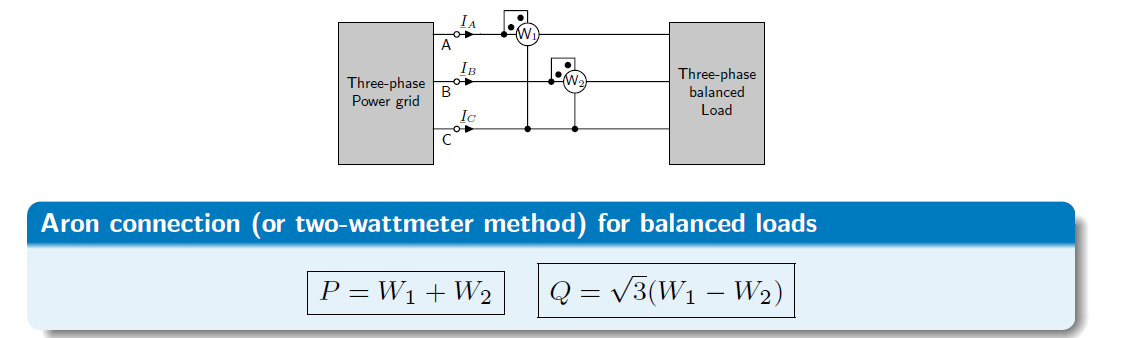

%aron watt meters

Uab=380*exp(1i*30*pi/180)

Uab = 3.2909e+02 + 1.9000e+02i

Ubc=380*exp(1i*-90*pi/180)

Ubc = 2.3268e-14 - 3.8000e+02i

Uca=380*exp(1i*-210*pi/180)

Uca = -3.2909e+02 + 1.9000e+02i

Uac=-Uca

Uac = 3.2909e+02 - 1.9000e+02i


W1=real(Uac*conj(Ia))

W1 = 1.1189e+04

W2=real(Ubc*conj(Ib))

W2 = 4.0060e+03


P=W1+W2

P = 1.5195e+04

Q=sqrt(3)*(W1-W2)

Q = 1.2442e+04

Equivalent estrella

%Tenim tensió i corrent

Uan=380/sqrt(3)*exp(1i*00)

Uan = 219.3931

Ubn=380/sqrt(3)*exp(1i*-120*pi/180)

Ubn = -1.0970e+02 - 1.9000e+02i

Ucn=380/sqrt(3)*exp(1i*120*pi/180)

Ucn = -1.0970e+02 + 1.9000e+02i


Za=Uan/Ia

Za = 5.6891 + 4.6581i

X=Za;disp(['Za=' num2str(abs(X)) ',' num2str(angle(X)*180/pi) 'A'])

Za=7.3528,39.31A


Zb=Ubn/Ib

Zb = 5.6891 + 4.6581i

X=Zb;disp(['Zb=' num2str(abs(X)) ',' num2str(angle(X)*180/pi) 'A'])

Zb=7.3528,39.31A


Zc=Ucn/Ic

Zc = 5.6891 + 4.6581i

X=Zc;disp(['Zc=' num2str(abs(X)) ',' num2str(angle(X)*180/pi) 'A'])

Zc=7.3528,39.31A


Compensem

Qdesitjada=0

Qdesitjada = 0

cosfi=1

cosfi = 1

Qbanc=Qdesitjada-Q

Qbanc = -1.2442e+04

%Qbanc=-3*w*Ctri*U^2
w=2*pi*50

w = 314.1593

Ctriangle=Qbanc/(-3*w*U^2)

Ctriangle = 9.1419e-05

CtriangleuF=Ctriangle*1e6

CtriangleuF = 91.4187